# Graph Connectivity Analysis Demo

### Non-SSR Digraph Example

A=[0 1 0 0 0 0 0;
   0 0 1 0 0 0 0; 
   1 0 0 0 0 0 0; 
   0 0 1 0 0 1 0; 
   0 0 0 1 0 0 0; 
   0 0 0 0 1 0 1; 
   1 0 0 0 0 0 0];
sc=cDigraphAnalysis(A);
[res,src,out]=sc.isProductive;
fprintf('Productive Graph: %s',mat2str(res));

Productive Graph: false

if ~isempty(src)
fprintf('Unreachable nodes from IN: %s\n',strjoin(src));end

Unreachable nodes from IN: N4 N5 N6 OUT


if ~isempty(out)
fprintf('Nodes that do not reach OUT: %s\n',strjoin(out));end

Nodes that do not reach OUT: IN N1 N2 N3


#### Plot Digraph

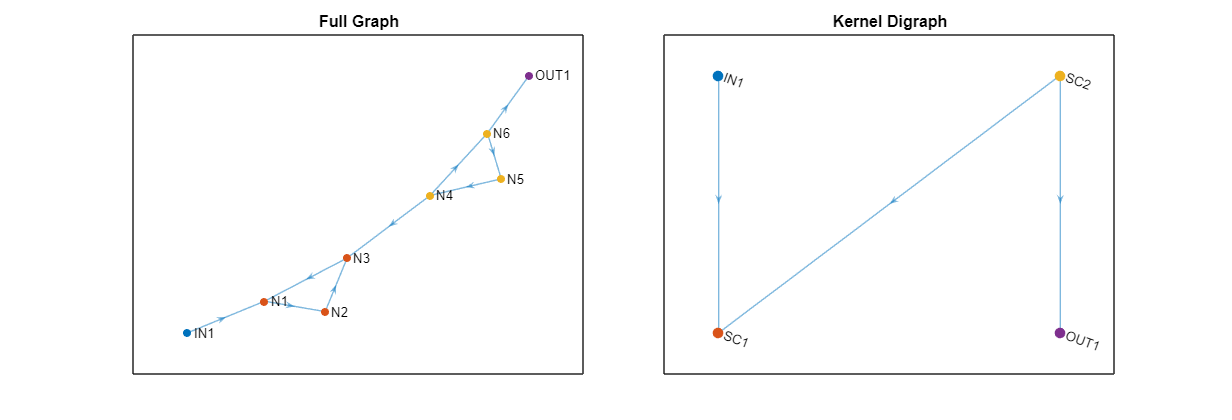

%Define figure size
pos=gcf().Position;
f=figure('Position',[0 0 2.2*pos(3) pos(4)]);
% Plot graph using tiled layout
tiledlayout(f,1,2,'TileSpacing','compact');
nexttile;
sc.plot(cType.DigraphType.GRAPH,'Full Graph');
nexttile;
sc.plot(cType.DigraphType.KERNEL,'Kernel Digraph');

### Productive Graph Example

A=[ 0  45 0  0  0  0  0; 
    0  0 15  0  0  0 25; 
    5  0  0  5  0  0  0; 
    0  0  0  0  0 40  0; 
    0  0  0 40  0  0  0; 
    0  0  0  0  5  0 30; 
   50  0  0  0 50  0  0];
sc=cDigraphAnalysis(A);
fprintf('Productive Graph: %s',mat2str(sc.isProductive));

Productive Graph: true

#### Plot Digraph

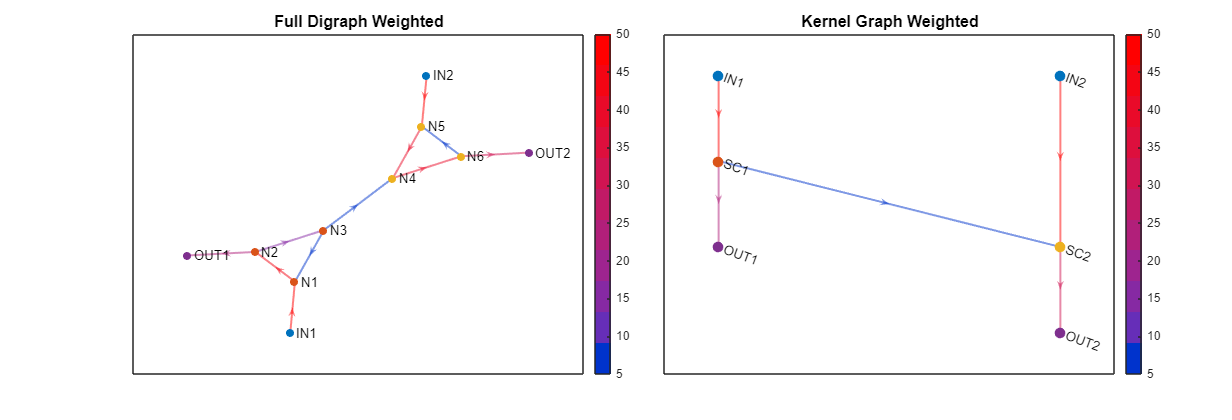

tiledlayout(f,1,2,'TileSpacing','compact');
nexttile;
sc.plot(cType.DigraphType.GRAPH_WEIGHT,'Full Digraph Weighted');
nexttile;
sc.plot(cType.DigraphType.KERNEL_WEIGHT,'Kernel Graph Weighted');

disp(getGroupsTable(sc));

    Name    Group
    ____    _____

    IN1      IN  
    IN2      IN  
    N1       SC1 
    N2       SC1 
    N3       SC1 
    N4       SC2 
    N5       SC2 
    N6       SC2 
    OUT1     OUT 
    OUT2     OUT 



disp(getKernelTable(sc));

             SC1    SC2    ENV    Total
             ___    ___    ___    _____

    SC1       0      5     25       30 
    SC2       0      0     30       30 
    ENV      50     50      0      100 
    Total    50     55     55        0 



### Additional Information

help cDigraphAnalysis

 cDigraphAnalysis - Analize the connectivity of a SSR Graph
    Calculate the transitive closure of the digraph,
    their strong conmponents and the Kernel DAG.
    The graph is represented by its adjacency matrix,
    and must have a single source node (IN) and a single output node (OUT).
 
    cGraphAnalysis constructor:
      obj = cDigraphAnalysis(A,names)
 
    cGraphAnalysis properties:
      NrOfNodes          - Number of nodes in the graph
      NrOfComponents     - Number of components
      GraphEdges         - Edges of the full graph
      GraphNodes         - Nodes of the full graph
      KernelNodes        - Nodes of the kernel DAG
      KernelEdges        - Edges of the kernel DAG
      isDAG              - Indicate if the graph is a DAG
    
    cGraphAnalysis methods:
      isProductive        - check if the SSR graph is productive
      isReachable         - check if two nodes are reacheable
      isStrongConnected   - chek if two nod

#### Local Functions

function res=getGroupsTable(obj)
 %getGroupsTable - Get the Groups Table
 % The Groups Table relates each node in the graph 
 % to the strong component to which it belongs.
    tmp=getGroupsInfo(obj);
    colNames=fieldnames(tmp);
    v1=categorical({tmp.Name}');
    v2=categorical({tmp.Group}');
    res=table(v1,v2,'VariableNames',colNames);
 end

 function res=getKernelTable(obj)
    [kA,kNames]=getKernelMatrix(obj);
    ktA=full([kA,sum(kA,2);sum(kA,1) 0]);
    ktNames=[kNames,'Total'];
    res=cell2table(num2cell(ktA),'VariableNames',ktNames,'RowNames',ktNames');
 end